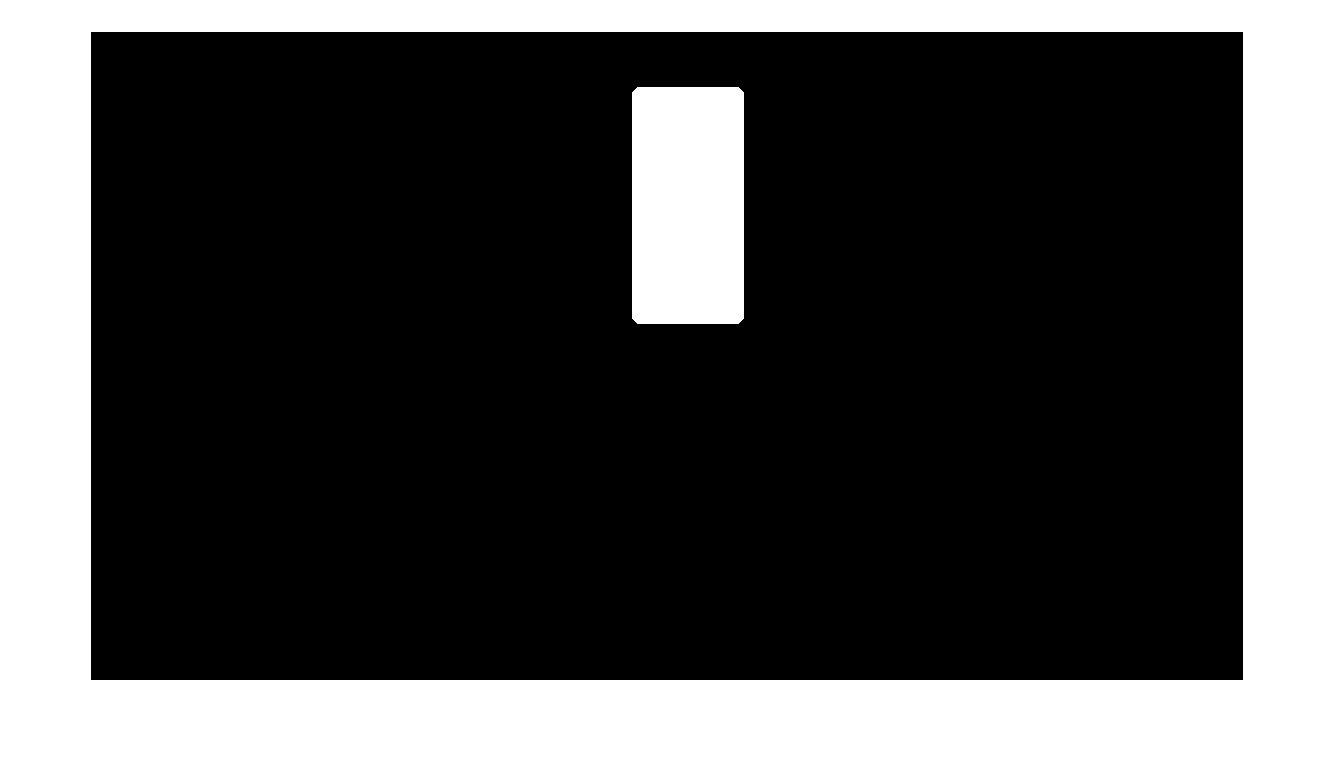

clear
close
clc

a=imread('C:\Users\Admin\Desktop\img.png');

b=rgb2gray(a);

c=0.5*(a(:,:,1)+a(:,:,2))-a(:,:,3);         %yellow detection

d=im2bw(c,0.4);
d=medfilt2(d,[10 10]);
imshow(d);

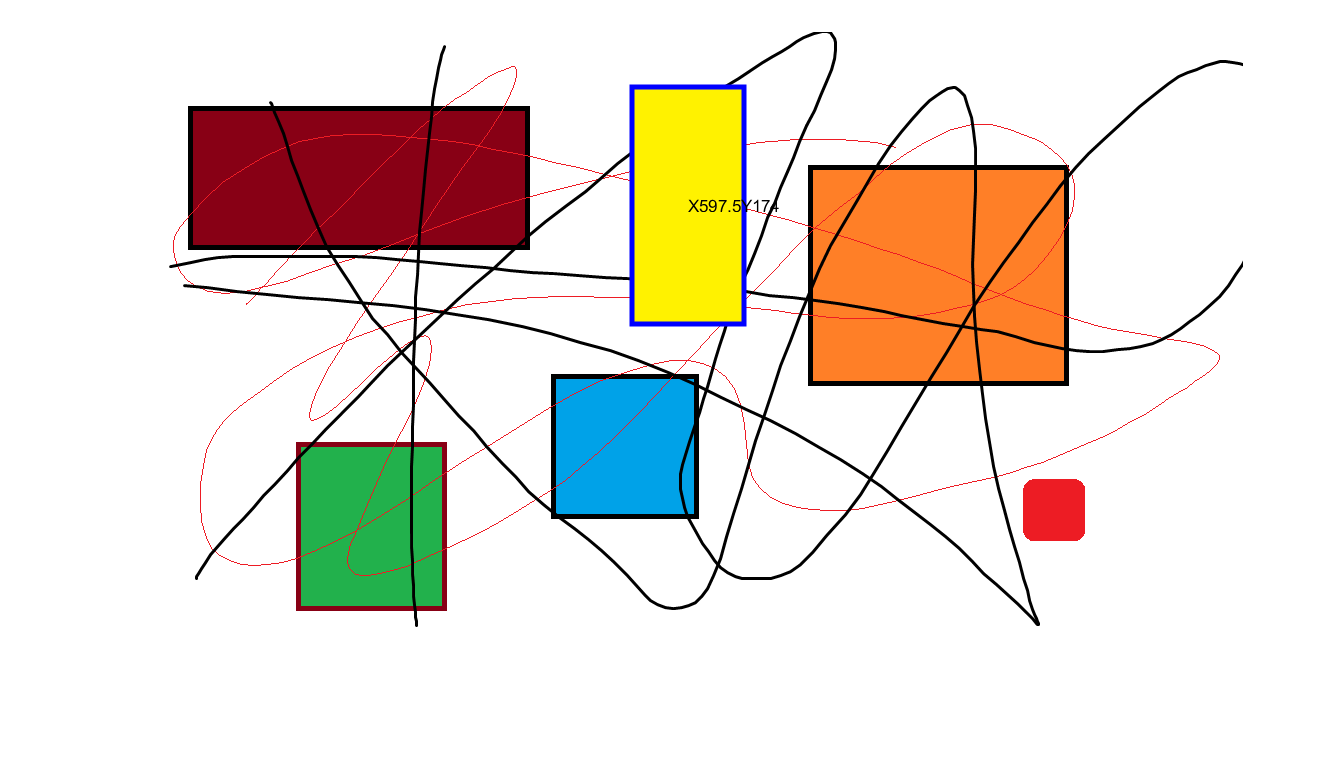

stat=regionprops(d,'BoundingBox','Centroid');

imshow(a);
hold on

for i=1:length(stat)
    B_b=stat(i).BoundingBox;
    cent=stat(i).Centroid;
    
    rectangle('Position',B_b,"EdgeColor",'b','LineWidth',3);
    text(cent(1),cent(2),strcat('X',num2str(cent(1)),'Y',num2str(cent(2))));
    plot(cent(1),cent(2),'b','MarkerSize',8)
end
hold off